%Parameters
R = 10; %Armature resistance (Ω)
L = 0.5e-3; %Armature inductance (H)
J = 0.10; %Rotor inertia (kg·m²)
B = 0.01; %Viscous friction coefficient (N·m·s)
Ke = 0.1; %Back emf constant (V·s/rad)
Kt = 0.1; %Torque constant (N·m/A)
V = 5; %Input voltage (V)


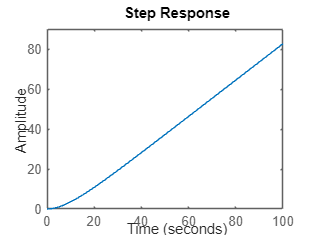

mech_sys=tf([1],[J B]);
elec_sys=tf([1],[L R]);

system=feedback(elec_sys*Kt*mech_sys,Ke);

%step(5*system,100)

s=tf('s');
system_pos=system/s;
step(system_pos,100)

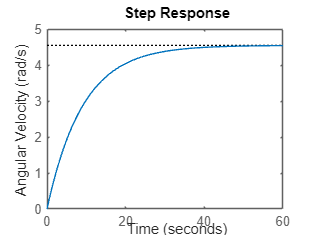


w_V=Kt/((L*s+R)*(J*s+B) + Kt*Ke);
step(5*w_V,60)
ylabel('Angular Velocity (rad/s)')

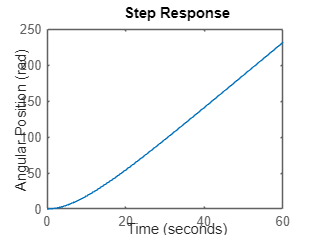


T_V=w_V/s;
step(5*T_V,60)
ylabel('Angular Position (rad)')